# First Order Ordinary Linear Systems : Sketch and Solve

% % Construct the domain
% t = pi/20 : pi/20 : 2*pi;
% Omega = polyshape({1.5*cos(t), 0.5+0.5*cos(t), 0.5+0.2*cos(t), -0.6+0.3*cos(t)}, ...
%                   {1.5*sin(t), 0.5*sin(t), 1+0.2*sin(t), -0.8+0.3*sin(t)});  % Omega
% 
% % Sloution Benchmark: poisson
% m  = 3 ;  % number of dependent variables
% u  = @(x,y) [sin(x.^2 + y.^2);  2*x.*cos(x.^2 + y.^2); 2*y.*cos(x.^2 + y.^2)]; % u=[phi, v1, v2]
% 
% % System Settings
% num_eq = 4;
% A1 = @(x,y) [1,0,0; 0,0,0; 0,-1,0; 0,0,1];
% A2 = @(x,y) [0,0,0; 1,0,0; 0,0,-1; 0,-1,0];
% A0 = @(x,y) [0,-1,0; 0,0,-1; 0,0,0; 0,0,0];
% f  = @(x,y) [0 ; 0; - 4*cos(x.^2 + y.^2) + 4*(x.^2 + y.^2).*sin(x.^2 + y.^2); 0];
% 
% % Sample Equation
% model = Collocation2D(m, Omega); % Construct the model
% model.gm.pdegplot(VertexLabels="on",EdgeLabels="on");
% 
% beta = 5 ; hmax=0.1 ;                    % mesh size, hmin=hmax/beta 
% model.discretize(hmax, beta, 'linear');   % Discretization
% 
% if true 
%     model.gm.pdemesh(); %(ElementLabels="on", NodeLabels="on") ;
%     hold on
%     edge = model.boundary_decompose();
%     for i = 1:model.gm.NumEdges
%         scatter(edge{i}(1:end-1,1), edge{i}(1:end-1,2), "filled")
%     end
%     hold off
%     fprintf('%d Nodes (%d unknowns) and %d Elements generated', size(model.gm.Mesh.Nodes,2), ...
%             size(model.gm.Mesh.Nodes,2)*m, size(model.gm.Mesh.Elements,2));
% end
% 
% 
% % Condition Settings
% num_cond = 2; B1 = []; B2 = [];
% B0 = @(x,y) [1,0,0; 0, model.boundary_normal([x,y], 2), -model.boundary_normal([x,y], 1)];
% g1 = @(x,y) sin(x.^2 + y.^2);
% g2 = @(x,y) model.boundary_normal([x,y]) * [-2*y.*cos(x.^2 + y.^2); 2*x.*cos(x.^2 + y.^2)];
% g  = @(x,y) [g1(x,y); g2(x,y)];
% 
% % Construct the model
% model.fitInterior(A1, A2, A0, f, num_eq);
% model.fitBoundary(B1, B2, B0, g, num_cond);
% model.fitTrueSol(u);
% 
% % Coordinates of the closed boundary nodes
% rng(42) ;  % random seed
% N_loc = max( ceil((1/hmax.^4)/(size(model.gm.Mesh.Elements,2))), 8);
% N_Gamma = max(ceil(1/hmax.^2), cellfun(@(x)size(x,1), model.Edges)) ;
% sampled_interior_nodes = model.sample_from_triangleMesh(model.gm.Mesh, N_loc);
% sampled_boundary_nodes = model.interp_multiedge_polyboundary(model.Edges, num2cell(N_Gamma));
% 
% N_Omega = size(sampled_interior_nodes, 1); N_Gamma = size(sampled_boundary_nodes, 1);
% fprintf('N_Omega: %d, N_Gamma: %d, total: %d', N_Omega, N_Gamma, N_Omega + N_Gamma);
% fprintf('eq_Omega: %d, eq_Gamma: %d, eq_total: %d', N_Omega*num_eq, N_Gamma*num_cond, N_Omega*num_eq + N_Gamma*num_cond);
% 
% % System assemble
% Lambda = diag(ones(1,num_cond)./hmax);     % square(weights) for BC
% [B_Omega, d_Omega, N_Omega] = model.Assemble_B_Omega(sampled_interior_nodes);
% [B_Gamma, d_Gamma, N_Gamma] = model.Assemble_B_Gamma(sampled_boundary_nodes, Lambda);
% B = [B_Omega ; B_Gamma];  d = [d_Omega ; d_Gamma];
% 
% fprintf('eq_Omega: %d, eq_Gamma: %d, eq_total: %d', N_Omega*num_eq, N_Gamma*num_cond, N_Omega*num_eq + N_Gamma*num_cond);
% fprintf('num_eq: %d, num_unknown: %d, ratio m/n: %.2f', size(B,1), size(B,2), size(B,1)/size(B,2));
% spy(B); c = B\d; model.C = model.reshape2mat(c);
% % save('./data/2DconvSample/2DconvSampleModel4.mat', 'model');

% load('./data/1D_SketchAndSolve_CollocationExample_01.mat');
addpath('./Skechers/');
data = {'./data/2DconvSample/2DconvSampleModel1.mat';
        './data/2DconvSample/2DconvSampleModel2.mat';
        './data/2DconvSample/2DconvSampleModel3.mat';
        './data/2DconvSample/2DconvSampleModel4.mat';
        './data/2DconvSample/2DconvSampleModel5.mat';
        './data/2DconvSample/2DconvSampleModel6.mat'};

% Construct the model
load('./data/2DconvSample/2DconvSampleModel_stat.mat')
h = [0.04, 0.05, 0.075, 0.1, 0.15, 0.2]; num_sample = length(h);
skt_coe = 4; rng(42); num_coworker = 50;

for j = 1:num_sample
    fprintf("Sample %d starts : ", j); load(data{j});
    B_Omega = model.Omega_assemble.B; d_Omega = model.Omega_assemble.d;
    B_Gamma = model.Gamma_assemble.B; d_Gamma = model.Gamma_assemble.d;
    B = [B_Omega ; B_Gamma]; d = [d_Omega ; d_Gamma]; [~, nB] = size(B_Omega);
    mS = skt_coe * nB;
    
    origin = struct();  % sample{13,j}
    origin.L2 = model.L2_error();
    origin.res = norm(B*reshape(model.C,[],1)-d);
    origin.sigmaB = svds(B, 1, 'smallest');

    origin.cond = svds(B, 1)/origin.sigmaB;

    sample{13,j} = origin;

    for i = 1:12
        fprintf("Sample %d starts : %d/12\n", j, i);
        sketcher = struct(); % sample{i,j}; % struct();

        % if (j == 1) && (ismember(i,1:9))
        %     continue
        % end

        switch i
            case 1
                if (j ~= 1) && (j~=2)
                    [SBd, ~] = sketching(mS, [B_Omega, d_Omega], 'Gaussian');
                else
                    sample{i,j} = struct();
                    continue
                end

            case 2
                [SBd, ~] = sketching(mS, [B_Omega, d_Omega], 'Hashing', {1, 'Regular'});

            case 3
                s = ceil(log(nB));
                [SBd, ~] = sketching(mS, [B_Omega, d_Omega], 'Hashing', {s, 'Regular'});

            case 4
                if (j ~= 1) && (j~=2)
                    [lev_score, ~, ~] = leverageScore(B_Omega,'Exact',[],'svd');
                    p = lev_score./sum(lev_score);
                    [SBd, ~] = sketching(mS, [B_Omega, d_Omega], 'Levscore', p);
                else
                    sample{i,j} = struct();
                    continue
                end

            case 5
                if (j ~= 1) && (j~=2)
                    [lev_score, ~, ~] = leverageScore(B_Omega,'Approx',[],'svd');
                    p = lev_score./sum(lev_score);
                    [SBd, ~] = sketching(mS, [B_Omega, d_Omega], 'Levscore', p);
                else
                    sample{i,j} = struct();
                    continue
                end

            case 6
                if (j ~= 1) && (j~=2)
                    [lev_score, ~, ~] = leverageScore(B_Omega,'Hashing_Approx',[],'svd');
                    p = lev_score./sum(lev_score);
                    [SBd, ~] = sketching(mS, [B_Omega, d_Omega], 'Levscore', p);
                else
                    sample{i,j} = struct();
                    continue
                end

            case 7
                [SBd, ~] = blockEmbedding(mS, [B_Omega, d_Omega], num_coworker, 'Gaussian');
            case 8
                [SBd, ~] = blockEmbedding(mS, [B_Omega, d_Omega], num_coworker, 'Hashing', {1, 'Regular'});
            case 9
                s = ceil(log(nB));
                [SBd, ~] = blockEmbedding(mS, [B_Omega, d_Omega], num_coworker, 'Hashing', {s, 'Regular'});  
            case 10
                [SBd, ~] = blockEmbedding(mS, [B_Omega, d_Omega], num_coworker, 'Levscore', {'Exact','svd'});
            case 11
                [SBd, ~] = blockEmbedding(mS, [B_Omega, d_Omega], num_coworker, 'Levscore', {'Approx','svd'});
            case 12
                [SBd, ~] = blockEmbedding(mS, [B_Omega, d_Omega], num_coworker, 'Levscore', {'Hashing_Approx','svd'});
        end

        SBd = [SBd; [B_Gamma, d_Gamma]]; 
        SB = SBd(:,1:end-1); Sd = SBd(:,end);
        sketcher.sol = SB\Sd;
        Cskt = model.reshape2mat(sketcher.sol);
        sketcher.L2 = model.L2_error(Cskt);
        sketcher.error = norm(sketcher.sol-reshape(model.C,[],1));
        sketcher.res = norm(B*sketcher.sol-d);
        k = (origin.res ./ sketcher.res).^2;
        sketcher.epsilon = (k-1)/(k+1);
        sketcher.error_bound = (origin.res./origin.sigmaB) * (2./(1-sketcher.epsilon));

        sketcher.sigmaB = svds(SB, 1, 'smallest');
        sketcher.cond = svds(SB,1)/origin.sigmaB;
        sample{i,j} = sketcher;
    end
    % save('./data/2DconvSample/2DconvSampleModel_stat.mat', 'sample');
end







    


load('./data/2DconvSample/2DconvSampleModel_stat.mat')

L2 = cellfun(@(x) x.L2,sample(13,:))

L2 =     0.0056    0.0077    0.0172    0.0312    0.0681    0.1955


h = [0.04, 0.05, 0.075, 0.1, 0.15, 0.2] 

h =     0.0400    0.0500    0.0750    0.1000    0.1500    0.2000


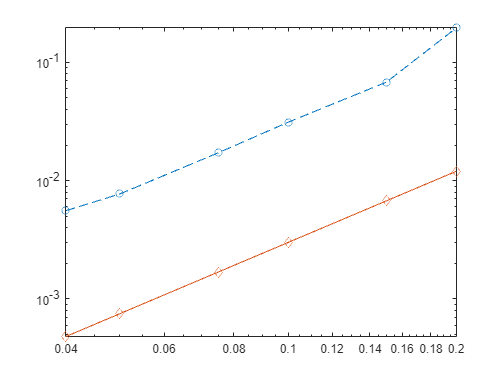

figure
loglog(h, L2, '--o', ...
       h, 0.3*h.^2, '-diamond') 

% Error Calculation
data.h = [] ;
data.min_sigB = [] ;
data.L2Error_wo_skt = [] ;
data.L2Error_wt_skt = [] ;

data.resi_full = [] ;
data.resi_skt  = [] ;
data.coe_error = [] ;
data.k_GQ = ((sqrt(skt_coe)+1)/(sqrt(skt_coe)-1)) * ones(1,num_sample) ;

for i = 1:num_sample
   
    model = sample{i}.model ;
    C_skt = model.reshape2mat(sample{i}.c_skt) ;

    abs_error_1 = @(x) abs(model.u(x) - model.evaluate_LSFEM_elewise(x)) ;
    abs_error_2 = @(x) abs(model.u(x) - model.evaluate_LSFEM_elewise(x,C_skt)) ;
    
    L2_1 = sqrt(integral(@(x) abs_error_1(x).^2, Omega(1), Omega(2), 'ArrayValued', true, 'AbsTol', 1e-12)) ;
    L2_2 = sqrt(integral(@(x) abs_error_2(x).^2, Omega(1), Omega(2), 'ArrayValued', true, 'AbsTol', 1e-12)) ;
    
    data.L2Error_wo_skt = [data.L2Error_wo_skt, L2_1] ;
    data.L2Error_wt_skt = [data.L2Error_wt_skt, L2_2] ;
    data.h = [data.h, sample{i}.model.gm.Mesh.MaxElementSize] ;

    data.resi_full = [data.resi_full, sample{i}.res_full] ;
    data.resi_skt  = [data.resi_skt, sample{i}.res_skt] ;
    data.coe_error = [data.coe_error, norm(sample{i}.c_full-sample{i}.c_skt)] ;
    data.min_sigB  = [data.min_sigB, svds(sample{i}.B, 1, 'smallest')] ;

end   


% save('./data/1D_SketchAndSolve_CollocationExample_01.mat', 'data');

% Plot the error
load('./data/1D_SketchAndSolve_CollocationExample_01.mat');
h = data.h ; 

loglog(h, data.L2Error_wo_skt(1,:), '--o', ...
       h, data.L2Error_wo_skt(2,:), '-o' , ...
       h, data.L2Error_wt_skt(1,:), '--^' , ...
       h, data.L2Error_wt_skt(2,:), '-^' , ...
       h, 0.3*h.^2, '-diamond', ...
       h, (data.L2Error_wo_skt(1,:)+data.coe_error), 'r-diamond') ;

legend("u1 w.o. sketching", ...
       "u2 w.o. sketching", ...
       "u1 w.t. sketching", ...
       "u2 w.t. sketching", ...
       "k = 2", ...
       '|| C_skt - C_ext ||_2', ...
       'Location', 'southeast') ;

title('L_2 Error VS mesh size h');


% Plot the sketching error
loglog(h, data.resi_skt, '--o', ...
       h, data.resi_full, '-o', ...
       h, data.k_GQ.*data.resi_full, '-*') ;

legend("sketching res", ...
       "full res", ...
       "predicted upper bound", ...
       'Location', 'northwest') ;

title('Discrete Residual VS mesh size h');


loglog(h, data.coe_error, '--o', ...
       h, (1+data.k_GQ).*data.resi_full./data.min_sigB, '-*',...
       h, 1*h.^1, '-diamond') ;

legend("sketching coe error", ...
       "predicted upper bound", ...
       "k = 1", ...
       'Location', 'northwest') ;

title('Discrete coefficient error VS mesh size h');

loglog(h, (data.L2Error_wo_skt(1,:)+data.coe_error)/20, '--o', ...
       h, (data.L2Error_wo_skt(2,:)+data.coe_error)/20, '-o' , ...
       h, data.L2Error_wt_skt(1,:), '--^' , ...
       h, data.L2Error_wt_skt(2,:), '-^' , ...
       h, 0.3*h.^2, '-diamond') ;

legend("u1 skt error bound", ...
       "u2 skt error bound", ...
       "u1 w.t. sketching", ...
       "u2 w.t. sketching", ...
       "k = 1", ...
       'Location', 'northwest') ;